% Robust fit of a single parametric model to data
%
% Mathematical Models and Methods, 2022
% Giacomo Boracchi, 
% Politecnico di Milano
% giacomo.boracchi@polimi.it 
% 
%
% Credits Luca Magri, Politecnico di Milano

addpath(genpath('.'))
clc;
clear;
close all;

%% model specification

cardmss = 2;          % minimum number of points required to fit a model

%% plotting params
BAND_WIDTH = 0.05;
BAND_COLOR = 'b';

%% create noisy dataset
x = linspace(0,1,100);
y = 1.5*x+1;
X = [x;y];
sigma = 0.01;
X = X + sigma.*randn(size(X));

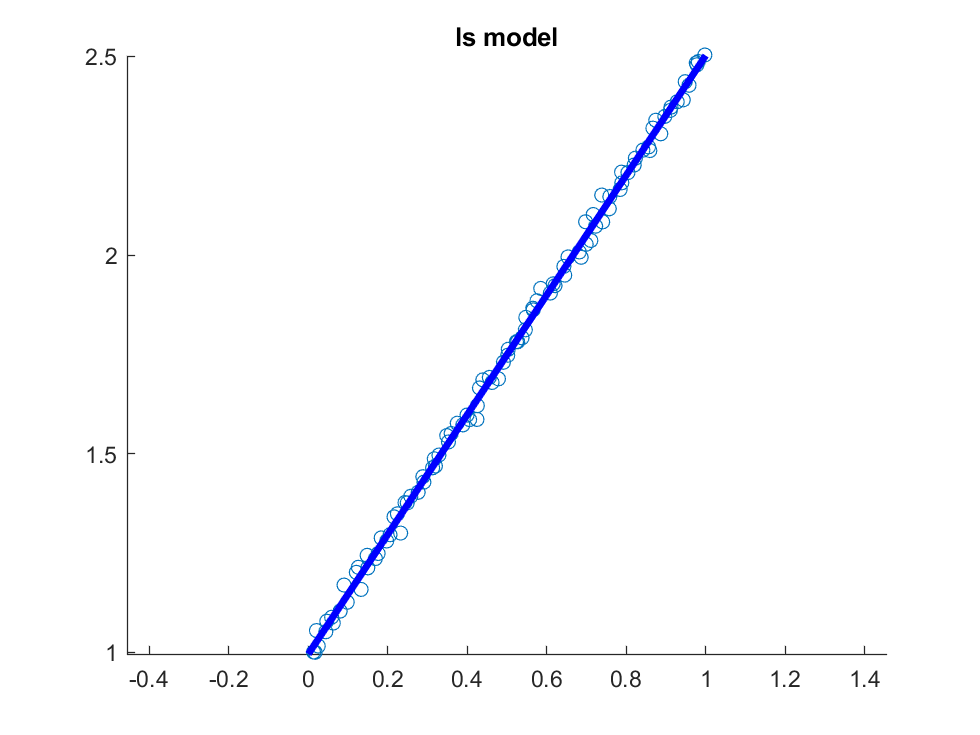

%% least square fit to noisy data
[model_OLS, res_OLS] = fit_line_ols(X);
figure(123); 
scatter(X(1,:),X(2,:));
axis equal;
hold on;
plot([0,1], [model_OLS(2), model_OLS(1) + model_OLS(2)], 'LineWidth', 3, 'Color', 'b') 
title('ls model');

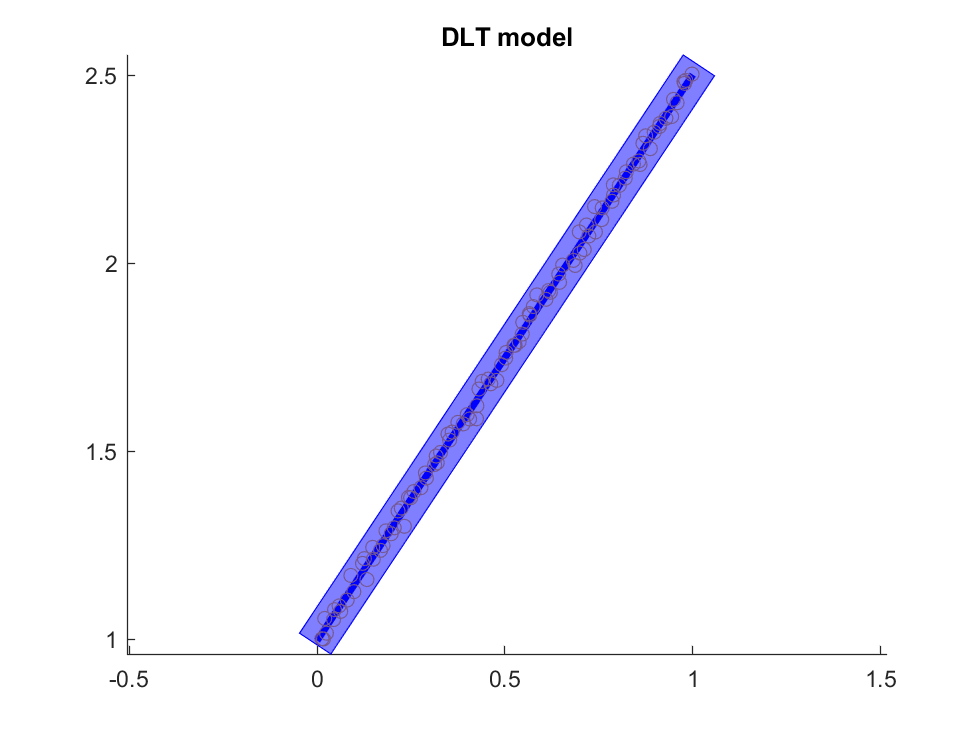

%% least square fit via DLT (different model parametrization)
[modelDLT, resDLT] = fit_line_dlt(X);

figure(124); 
scatter(X(1,:),X(2,:));
hold on;
display_band(X, modelDLT, BAND_WIDTH, BAND_COLOR);
axis equal;
title('DLT model');

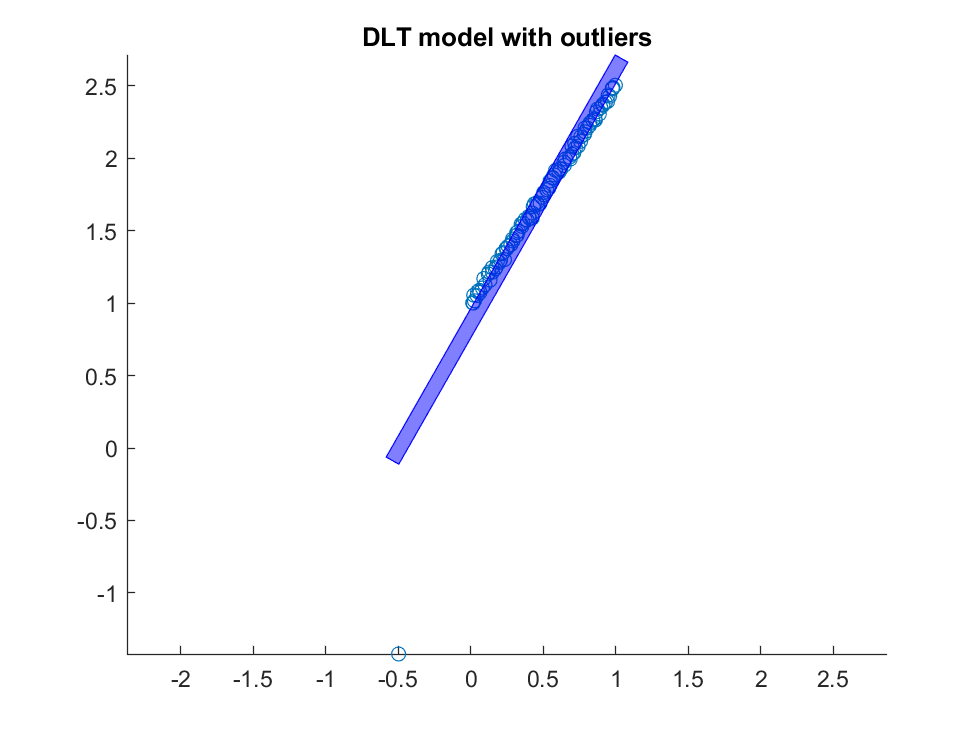

%% add a single oultier
x_new = randn(2,1);
X_new = [X, x_new];
modelDLT = fit_line_dlt(X_new);

figure(123); cla
scatter(X_new(1,:),X_new(2,:));
hold on;
display_band(X_new, modelDLT, BAND_WIDTH, BAND_COLOR);
axis equal;
title('DLT model with outliers');

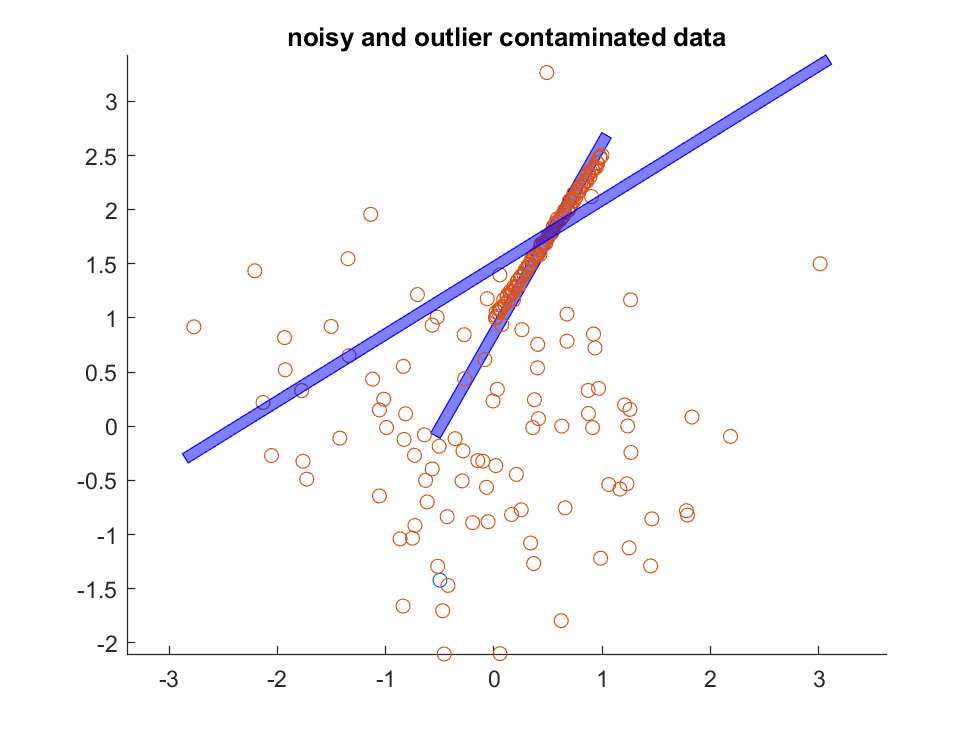

%Add Many outliers
n_outliers = 100;
x_new = randn(2,n_outliers);
X_new = [X, x_new];

% fit a line using DLT
modelDLT = fit_line_dlt(X_new);

figure(125); 
scatter(X_new(1,:),X_new(2,:));
hold on;
display_band(X_new, modelDLT, BAND_WIDTH , BAND_COLOR);
title('noisy and outlier contaminated data');
axis equal;

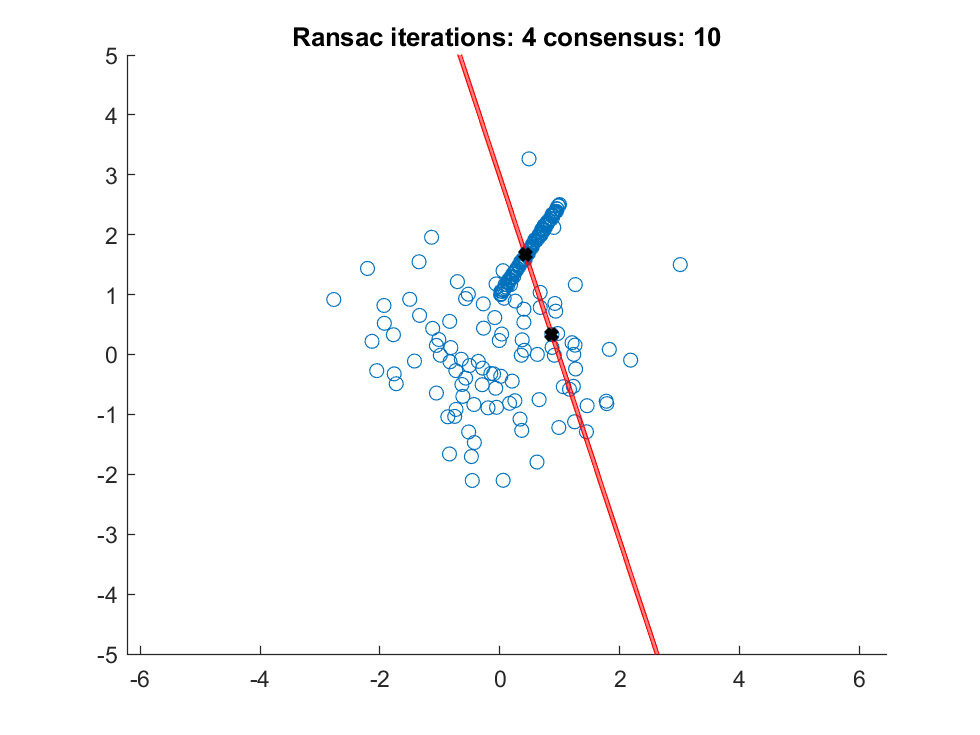

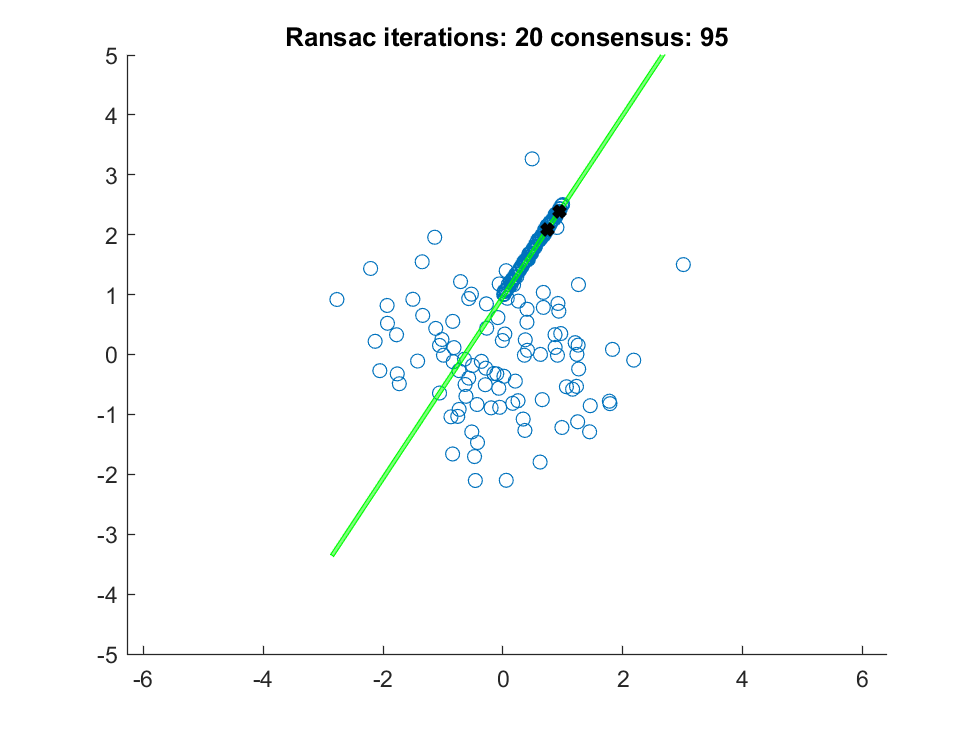

Ransac reached 20 iterations


%% ransac
epsi = 3*sigma; % define inlier threshold
displayRun = true; % true to show iterations of Ransac

% invoke simpleRANSAC
 
[bestmodel, bestinliers] = simpleRANSAC(X_new, cardmss, epsi, displayRun);

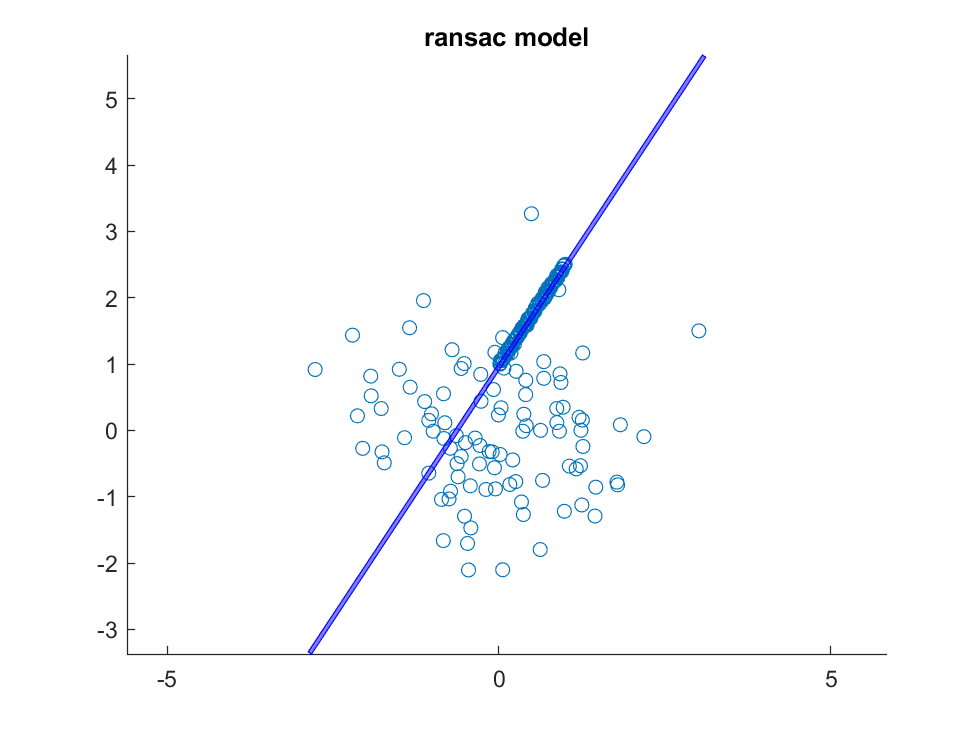


% refine model estimates
refinedModel = fit_line_dlt(X_new(:, bestinliers));

figure; 
scatter(X_new(1,:),X_new(2,:));
hold on;
display_band(X_new, bestmodel, epsi , BAND_COLOR);
axis equal;
title('ransac model');

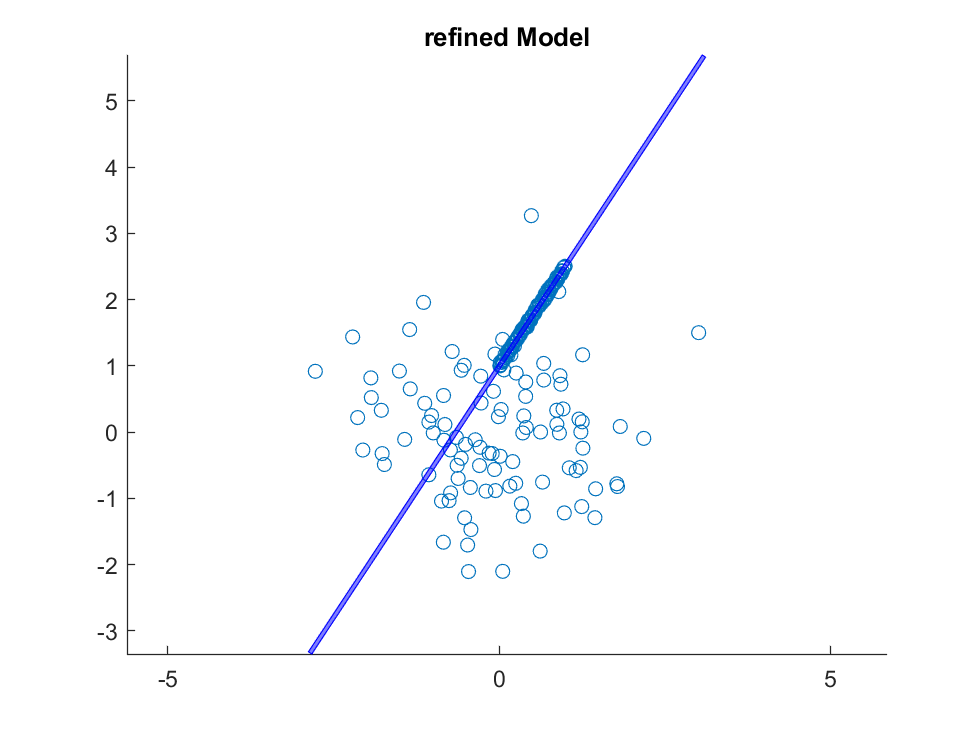



figure; 
scatter(X_new(1,:),X_new(2,:));
hold on;
display_band(X_new, refinedModel, epsi , BAND_COLOR);
axis equal;
title('refined Model');

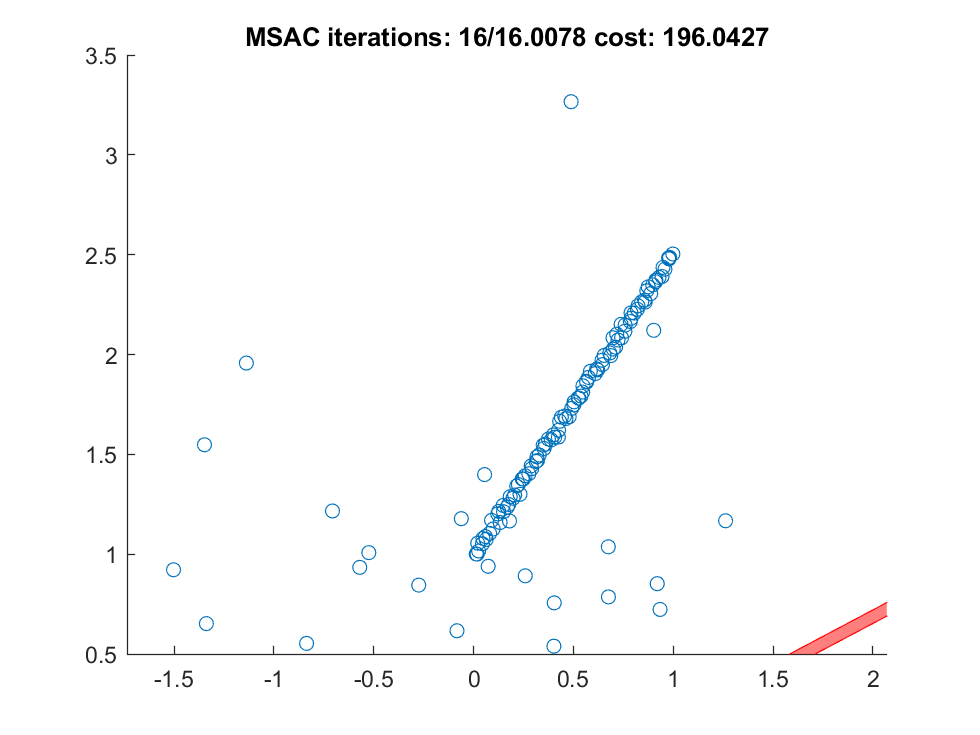

MSAC reached 15 iterations


%% MSAC 
displayRun = true;
% invoke simpleMSAC
[bestmodel, bestinliers] = simpleMSAC(X_new, cardmss, epsi, displayRun);

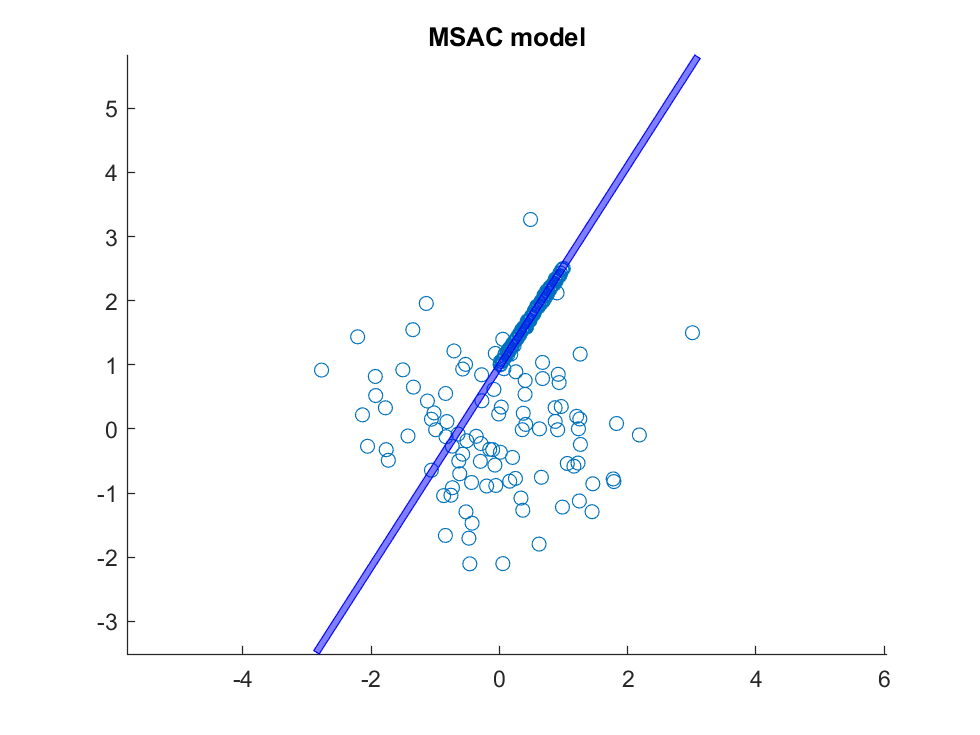


% refine model estimates
refinedModel =  fit_line_dlt(X_new(:, bestinliers));

figure; 
scatter(X_new(1,:),X_new(2,:));
hold on;
display_band(X_new, bestmodel, BAND_WIDTH , BAND_COLOR);
axis equal;
title('MSAC model');

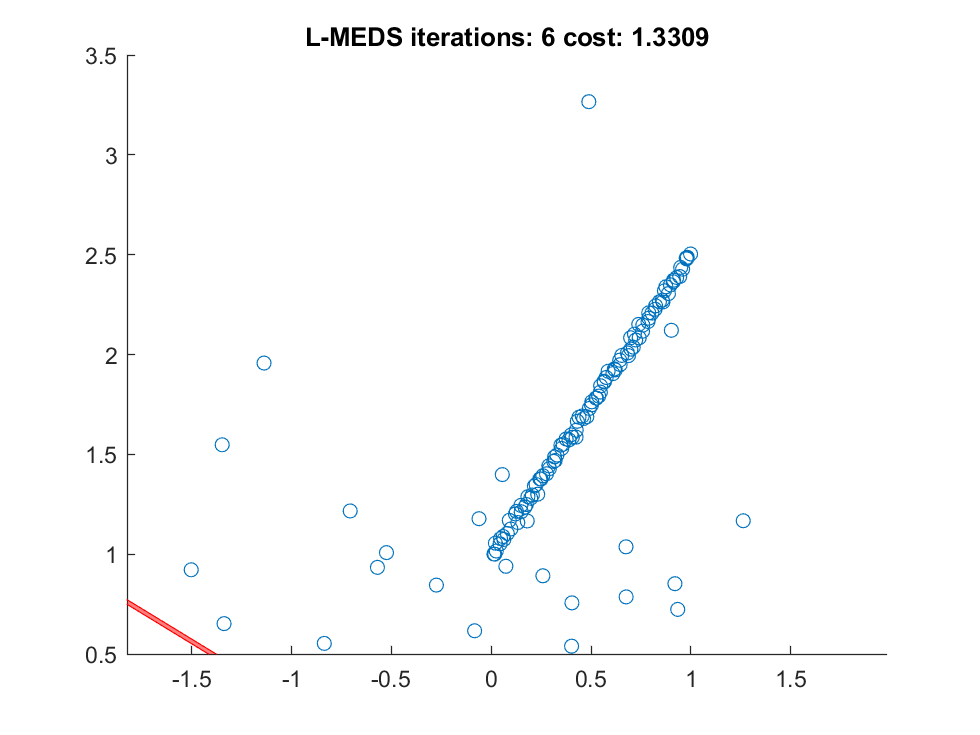

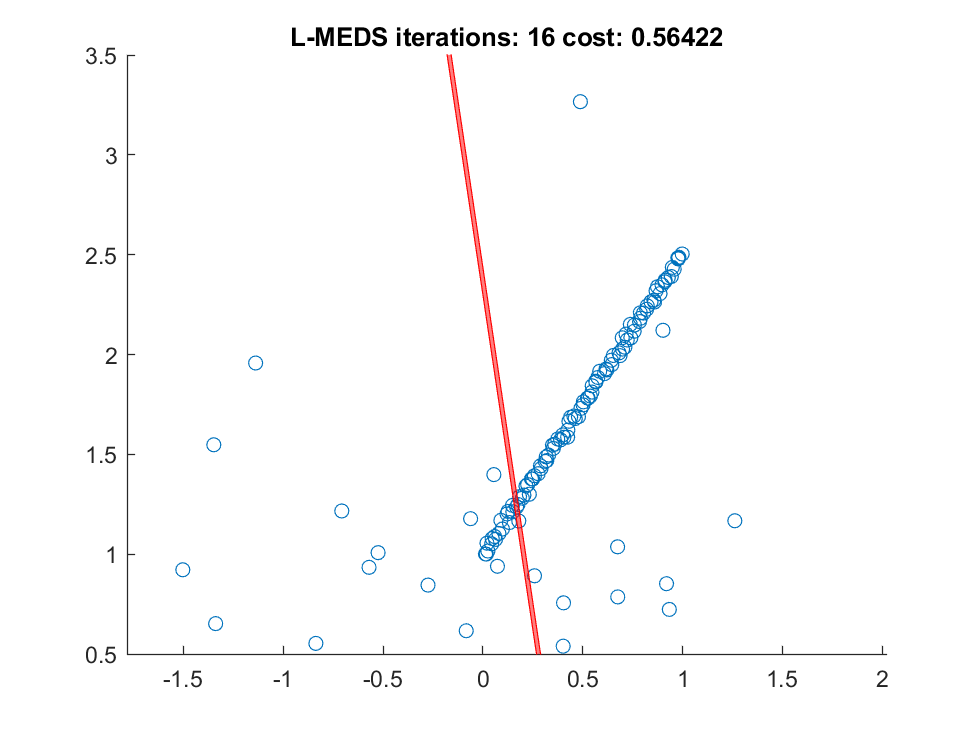

Lmeds reached 15 iterations


%% lmeds (does not require the inlier threhsold but has a 0.5 breakpoint)
displayRun = true;
% invoke simpleLMEDS
[bestmodel, bestinliers] = simpleLMEDS(X_new, cardmss, displayRun);

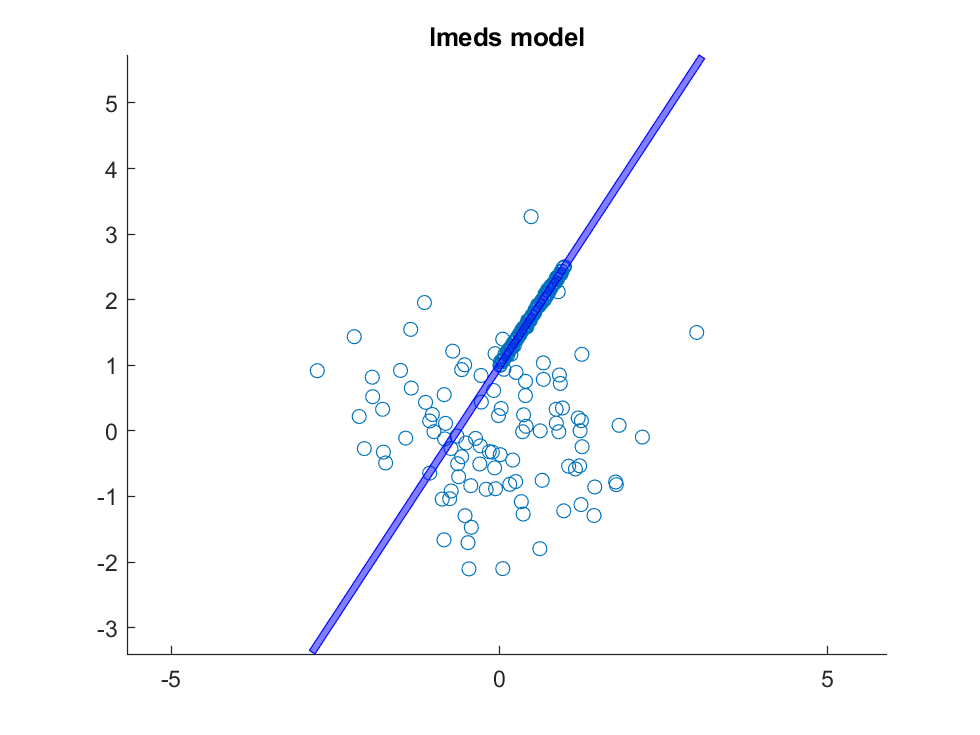


% refine model estimates
refinedModel =  fit_line_dlt(X_new(:, bestinliers));

figure; 
scatter(X_new(1,:),X_new(2,:));
hold on;
display_band(X_new, bestmodel, BAND_WIDTH , BAND_COLOR);
axis equal;
title('lmeds model');